clear; close all;

% Load data
load("2_data\benchmark_references_double_pendulum_v2.mat");

% Setup MRT-MOLE
mrt_mole = CMRTMOLE(@run_double_pendulum_feedforward_dynamics, 1, 4, [1, 0, 1, 0], 3);

% Number runs
K = size(rc, 2);

% Number references
W = size(rc, 1);

% Number trials per reference
J = 8; 

% Allocate error cell
ec = cell(K, 1);

% Run MRT-MOLE
parfor k = 1:K
    disp("Run " + num2str(k));
    % Setup MRT-MOLE
    mrt_mole = CMRTMOLE(@run_double_pendulum_feedforward_dynamics, 1, 4, [1, 0, 1, 0], 3);

    tic; 
    ec{k,1} = mrt_mole.run_mrt_mole(rc(:, k), J, uc);
    toc;
end

Run 1
Run 2
Run 3
Run 4
Run 5
Run 6
> In classreg.learning.impl.GPImpl>iInitializeGamma0 (line 3322)
In classreg.learning.impl/GPImpl/estimateThetaHatSigmaHatExact (<

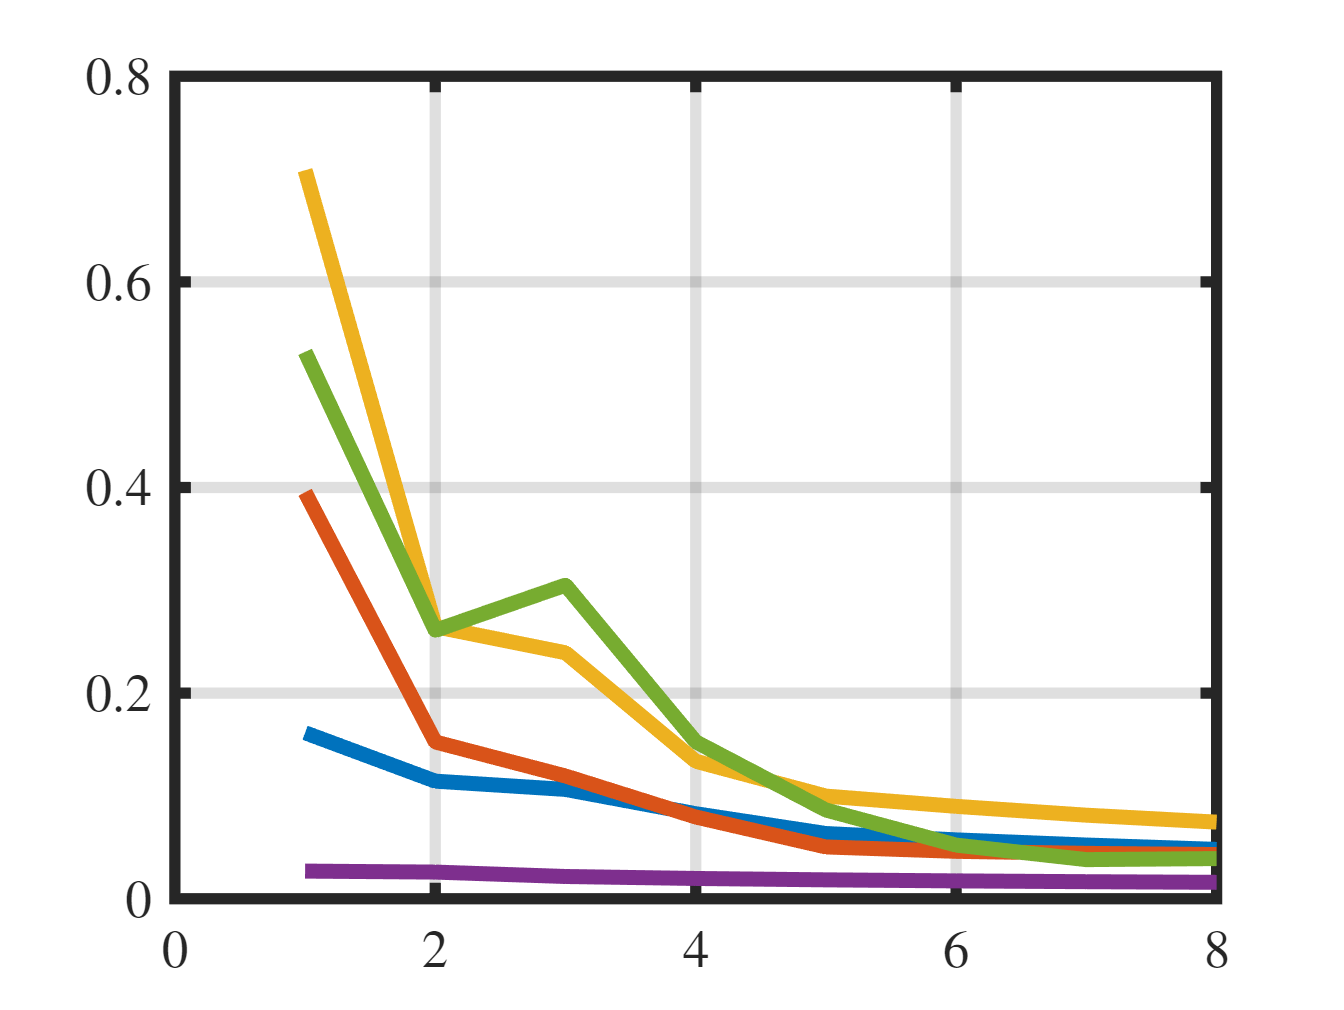


% Reorder errors
ewc = cell(W, 1);
for w = 1:W
    ewc{w,1} = zeros(J, K);
end

for k = 1:K
    emat = ec{k,1};
    for w = 1:W
        ewc{w,1}(:, w) = emat(:, w);
    end
end

% Plot results
figure;
for w = 1:W
    plot(median(ec{w,1}, 2)); hold on;
end


save("2_data\results_benchmark_double_pendulum.mat", "ec");